# Tutorial: Fundamentals

## Input and output

disp('Hello World')

Hello World


guess = input('Guess a number from 1 to 100')

guess = 1

## Cleaning up

Removes all varialbes form the workspace

clear all

Clears the contents of the command window

clc

Deletes all figures

close all

## Math operations

round(200*2.25/1.5) % Reounds to the nearest integer

ans = 300

## Array operations

Create an array of size 10, where elements are linear-spaced from 1 to 100

array = linspace(1, 100, 10)

array =      1    12    23    34    45    56    67    78    89   100


Array indexing

array(1)

ans = 1

array(2:4)

ans =     12    23    34


array(2:end)

ans =     12    23    34    45    56    67    78    89   100


Start at 1, count by 2 and stop when the count reaches the end

array(1:2:end)

ans =      1    23    45    67    89


Start at the last index, count by -2 and stop when the count reaches 1

array(end:-2:1)

ans =    100    78    56    34    12


Select the first, fourth and fifth element of this array:

array([1 4 5])

ans =      1    34    45


Transpose operator

array.'

ans =      1
    12
    23
    34
    45
    56
    67
    78
    89
   100


## Matrix operations

Create a matrix:

matrix = [1 2 3; 4 5 6; 7 8 9;]

matrix =      1     2     3
     4     5     6
     7     8     9


Get the first element

matrix(1, 1)

ans = 1

Extract a submatrix (rows 1 and 2 and columns 1, 2, 3)

matrix([1 2], [1 2 3])

ans =      1     2     3
     4     5     6


Same result:

matrix(1:2, 1:3)

ans =      1     2     3
     4     5     6


Get the third column

matrix(:, 3)

ans =      3
     6
     9


Get all elements of the matrix as an array (arranged in column order)

matrix(:)

ans =      1
     4
     7
     2
     5
     8
     3
     6
     9


Above expression is useful, when we compute the sum of all elements in a matrix:

sum(matrix(:))

ans = 45

Logical indexing

special_index = logical([1 0 0; 0 0 1; 0 0 0])

special_index = 3×3 logical array
   1   0   0
   0   0   1
   0   0   0


matrix(special_index)

ans =      1
     6


Can also be used to assign values

matrix(special_index) = [1 6]

matrix =      1     2     3
     4     5     6
     7     8     9


Linear indexing

H = hilb(4)

H =     1.0000    0.5000    0.3333    0.2500
    0.5000    0.3333    0.2500    0.2000
    0.3333    0.2500    0.2000    0.1667
    0.2500    0.2000    0.1667    0.1429


H([2 11])

ans =     0.5000    0.2000


Linear indexing is useful for extracting a set of pixel values from arbitrary locations e.g., (1,3), (2,4) and (4,3)

row_indices = [1 2 4];
column_indicies = [3 4 3];
M_of_H = size(H, 1);
% Computes: linear_indicies = M_of_H * (column_indicies-1) + row_indices
linear_indicies = sub2ind(size(H), row_indices, column_indicies)

linear_indicies =      9    14    12


H(linear_indicies)

ans =     0.3333    0.2000    0.1667


When a matrix has a large number of 0s, then use a sparse matrix:

A = [1 0 0; 0 3 4; 0 0 5]

A =      1     0     0
     0     3     4
     0     0     5


sparse_A = sparse(A)

sparse_A =    (1,1)        1
   (2,2)        3
   (2,3)        4
   (3,3)        5


original_A = full(sparse_A)

original_A =      1     0     0
     0     3     4
     0     0     5


Important standard arrays:

zeros(2, 2)

ans =      0     0
     0     0


ones(2, 2)

ans =      1     1
     1     1


true(2, 2)

ans = 2×2 logical array
   1   1
   1   1


false(2, 2)

ans = 2×2 logical array
   0   0
   0   0


magic(4)

ans =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


eye(4) % 4x4 Identity matrix

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


rand(2, 2) % uniformly distributed in the interval [0 1] 

ans =     0.0681    0.7898
    0.7452    0.0470


randn(2,2) % Gaussian distributed

ans =     0.3030   -0.3789
   -0.7724    1.5691


## Cell arrays

Cell arrays is like  n-tuples. They provide a way to compine a mixed set of objects into a variable.

tuple = {1, 'Hello World', 1.3}

tuple = 1×3 cell array
    {[1]}    {'Hello World'}    {[1.3000]}


See the contents of a cell array:

celldisp(tuple)

 
tuple{1} =
 
     1

 
 
tuple{2} =
 
Hello World
 
 
tuple{3} =
 
    1.3000

 


Apply a function to each element of the cell array:

cellfun('length', tuple)

ans =      1    11     1


## Structures

Create a struct

image_struct.name = 'Lena'

image_struct = struct with fields:
    name: 'Lena'


image_struct.image = imread('lena.jpg')

image_struct = struct with fields:
     name: 'Lena'
    image: [512×512 uint8]


Array of structs:

image_struct(2).name = 'Festia'

image_struct = 1×2 struct array with fields:
    name
    image


image_struct(2).image = imread('festia.jpg')

image_struct = 1×2 struct array with fields:
    name
    image


## Reading images

Get detailed information about an image:

K = imfinfo('lena.jpg')

K = struct with fields:
           Filename: '/home/omar/code/cvml/Lab1/lena.jpg'
        FileModDate: '25-Aug-2015 19:39:10'
           FileSize: 155707
             Format: 'jpg'
      FormatVersion: ''
              Width: 512
             Height: 512
           BitDepth: 8
          ColorType: 'grayscale'
    FormatSignature: ''
    NumberOfSamples: 1
       CodingMethod: 'Huffman'
      CodingProcess: 'Progressive'
            Comment: {}


Read an image into an array `f`. Note that semicolon is used to supress output

f = imread('lena.jpg'); 

Show the row and column dimensions of an image

size(f)

ans =    512   512


Store the dimensions of a 2D image in variables

[M, N] = size(f);

M = size(f, 1); % Size of first dimension
N = size(f, 2); % Size of the second dimension

A single dimension is any dimension `d` for which `size(array, d)=1`

## Displaying images

Display an image

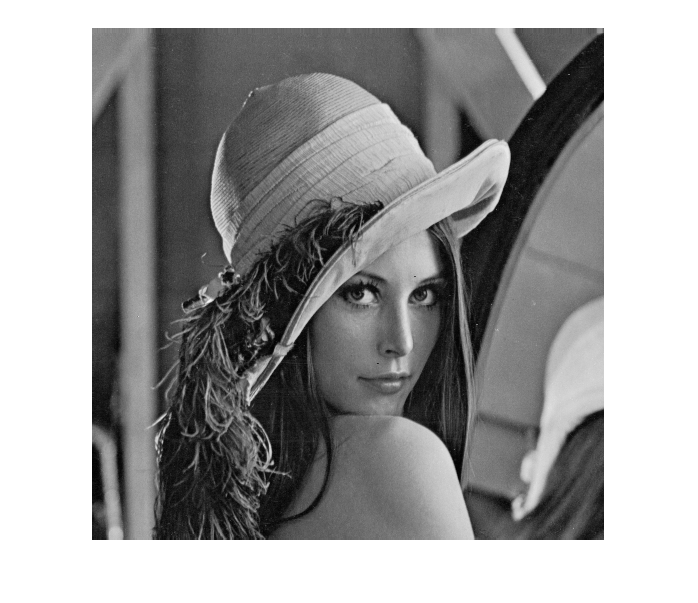

imshow(f)

Dynamic range (contrast/brightness) describes the measurement between maximum and minimum values in an image. If an image has low dynamic range, use follow function to scale up the range:

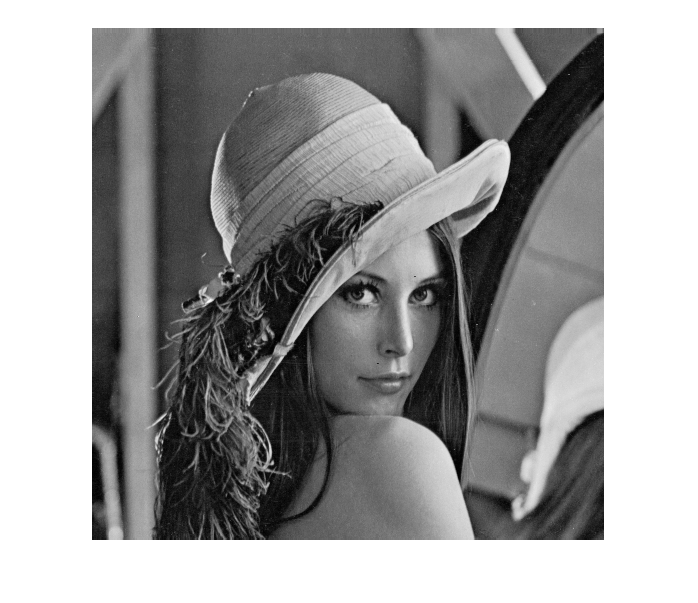

imshow(f, [ ])

If imshow() function is called again with another image MATLAB replaces the image in the figure window with the new image. To keep the first, we need to use the figure() function, which creates a new Figure window

figure()

Flip image vertically:

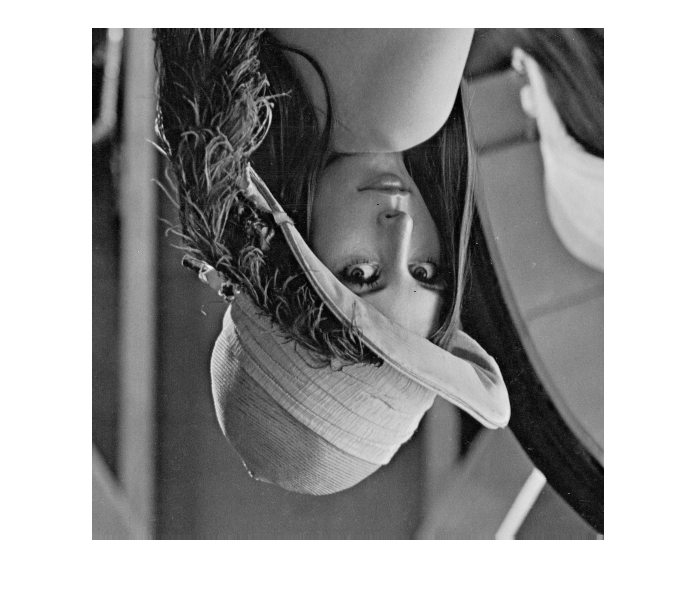

vflipped = f(end:-1:1, :);
imshow(vflipped)

Flip horizontally:

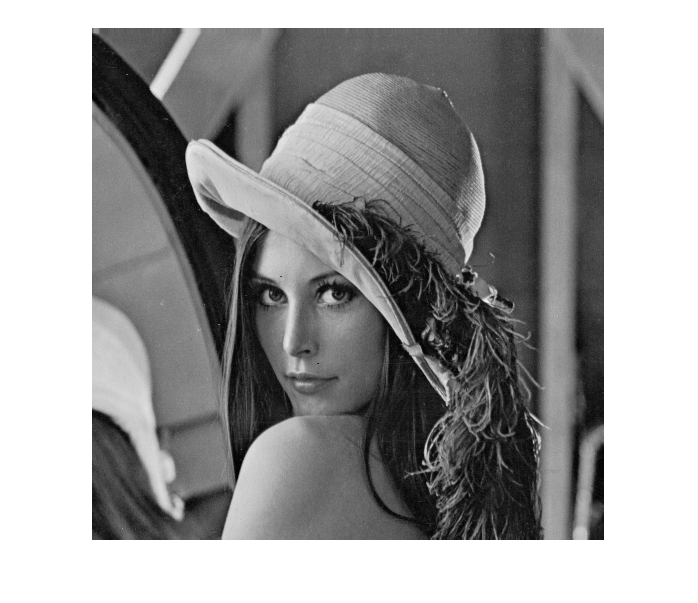

hflipped = f(:, end:-1:1);
imshow(hflipped)

Image cropping:

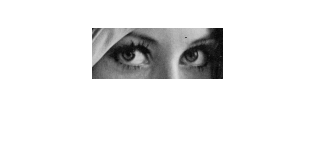

imshow(f(240:290, 230:360))

Subsampling (resizing) image:

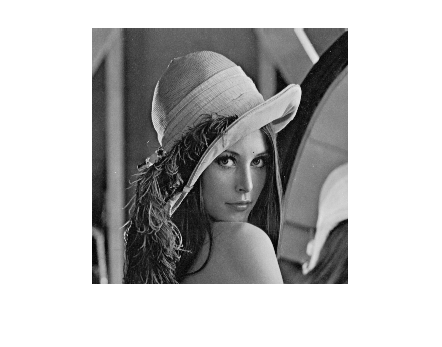

imshow(f(1:2:end, 1:2:end))

Plot a horizontal scan line through the middle of the image:

middle_row = round(size(f, 1) / 2)

middle_row = 256

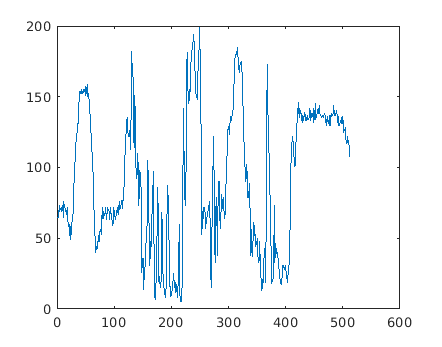

plot(f(middle_row, :))

Mark the row that we have plotted:

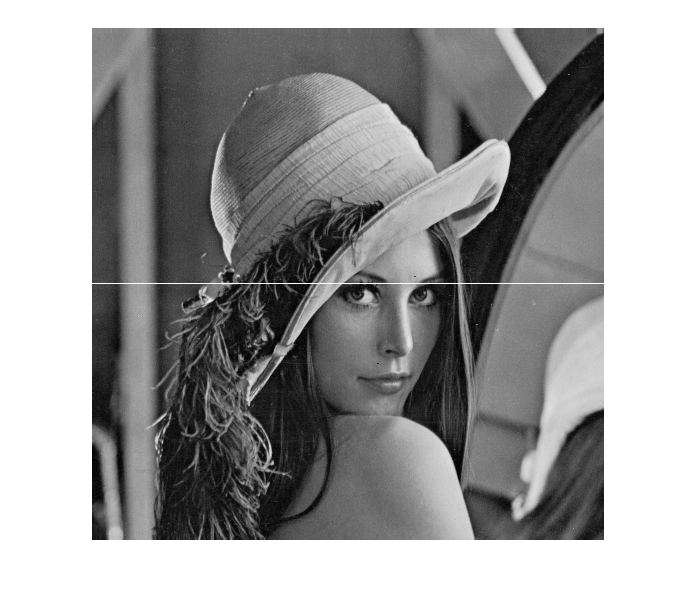

temp = f; temp(middle_row, :) = 255; imshow(temp)

Image Tool is more interactive.

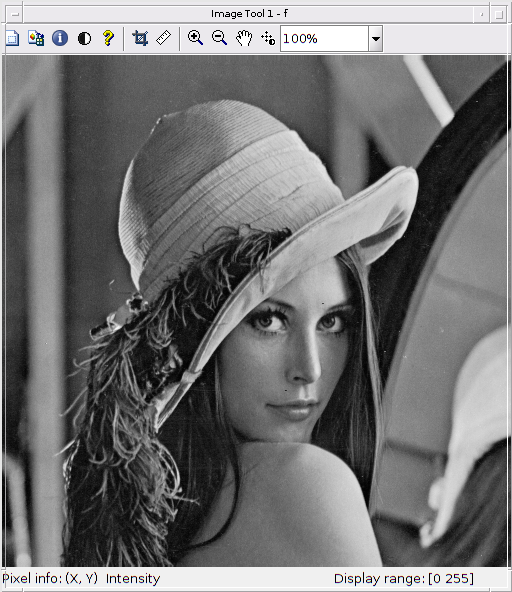

imtool(f)

## Saving images

Save image to current folder

imwrite(f, 'newname.jpg', 'quality', 100)